clear all; close all; clc 

%%% In this example,we train a Linear and a Quadratic classifier using data
%%% from 10,100 and 1000 samples respectively.first,in each case, validation and training data are
%%% generated using 2D and 3D Gaussian mixtures. classifiers are trained
%%% and Linear and Quadratic trained weights are generated using Gradient
%%% and stochastic gradient desncet algorithms.
%%% These weights are used after to classify the validation data. Classification results
%%% are plotted for the 2D and 3D case respectiveley, where in each case,
%%% Linear and quadratic classifiers results trained using  10, 100 and
%%% 1000 respectively are plotted too.

%% 2D case
% set-up: givene parameters and validation data
% given parameters

 % Specify number of feature dimensions 
NTrain = [10;100;1000]; % Specify number of training samples for experiments
NVal = 10000; % Specify number of validation samples for experiments

% Specify data pdf
gmmParameters.priors = [0.9,0.1]; % class priors
gmmParameters.meanVectors = [-2 2;-1 1];
gmmParameters.covMatrices(:,:,1) = [2 -0.9 ;-0.9 1 ]; 
gmmParameters.covMatrices(:,:,2) = [2 -0.9 ;-0.9 3 ];
epsilon = 1e-3; % stopping criterion threshold/tolerance
alpha = 1e-2; % step size for gradient descent methods

% Generate iid validation samples
disp('Generating the validation data set.'),

Generating the validation data set.


Generating the training data set; Ntrain =10


Training the logistic-linear model with gradient descent.


Training the logistic-linear model with stochastic gradient descent.


Training the logistic-quadratic model with gradient descent.


Training the logistic-quadratic model with stochastic gradient descent.


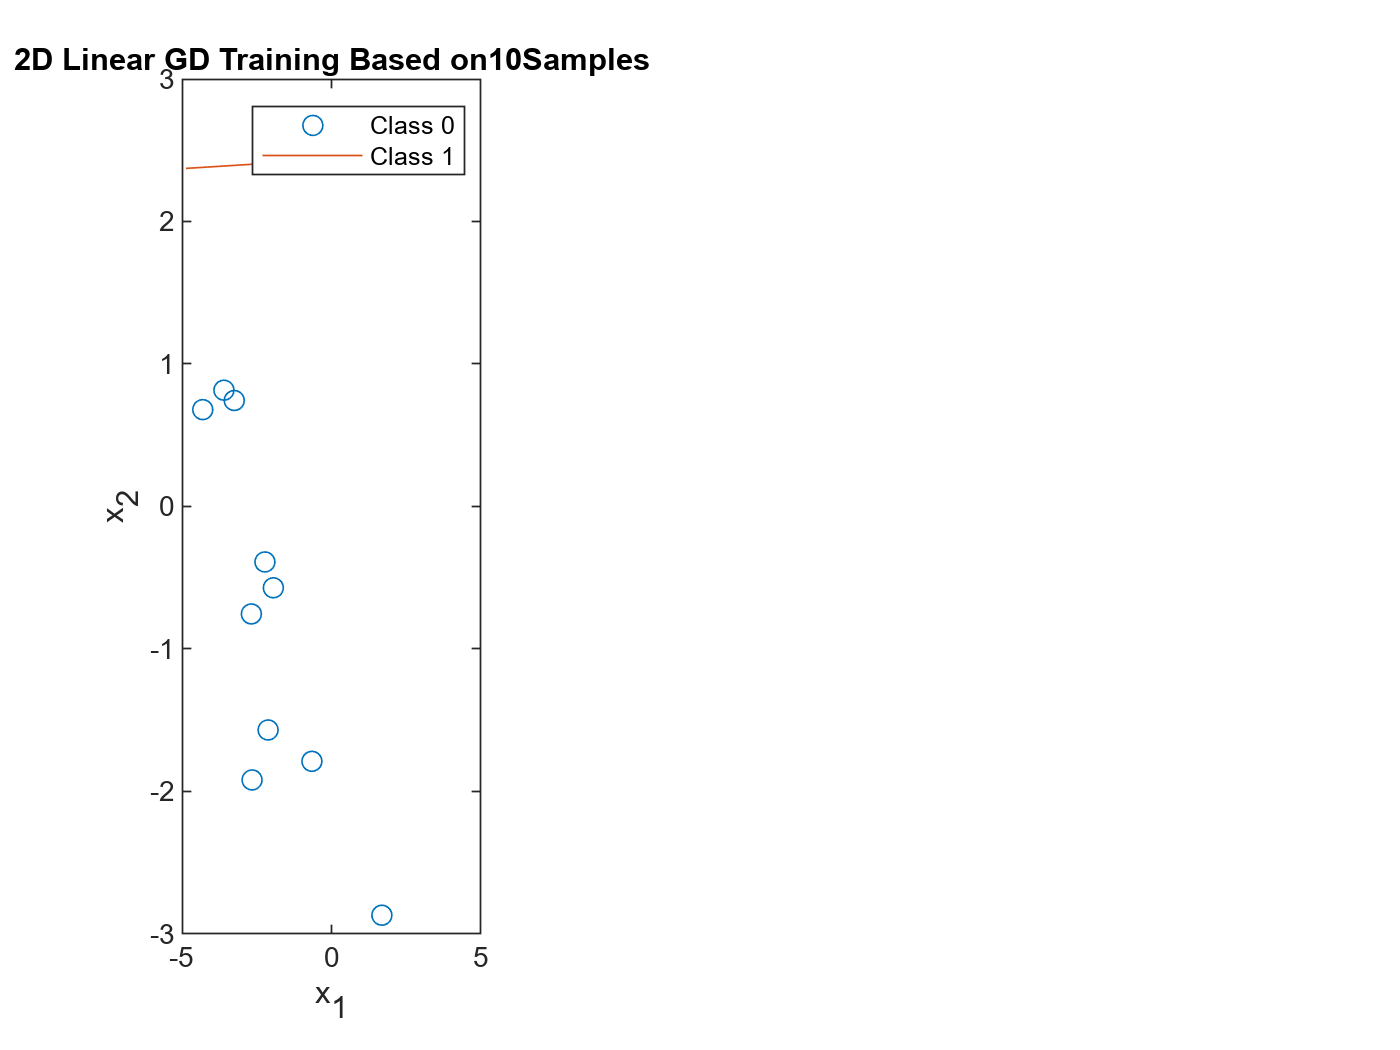

[xVal,componentLabels] = generateDataFromGMM(NVal,gmmParameters,0);
n = size(xVal,1);
labelsVal = componentLabels - 1; % convert 0/1 component labels to 0/1 class labels
NcVal = [length(find(labelsVal==0)), length(find(labelsVal==1))];

for i=1:length(NTrain) % Conduct experiments with different amounts of training samples
    disp(strcat('Generating the training data set; Ntrain = ',num2str(NTrain(i)))),
    % Generate iid training samples as specified
    [xTrain{i},componentLabels] = generateDataFromGMM(NTrain(i),gmmParameters,0);
    labelsTrain{i} = componentLabels - 1; % convert 0/1 component labels to 0/1 class labels
    NcTrain{i} = [length(find(labelsTrain{i}==0)), length(find(labelsTrain{i}==1))];
    
    disp('Training the logistic-linear model with gradient descent.'),
    % Deterministic (batch) gradient descent 
    % Uses all samples in training set for each gradient calculation
    paramsGD.type = 'batch';
    paramsGD.ModelType = 'logisticLinear';
    paramsGD.stepSize = alpha;
    paramsGD.stoppingCriterionThreshold = epsilon;
    paramsGD.minIterCount = 10;
    [wGradDescentLin,zLin] = gradientDescent_binaryCrossEntropy(xTrain{i},labelsTrain{i},paramsGD);

    disp('Training the logistic-linear model with stochastic gradient descent.'),
    % Stochastic (with mini-batch) gradient descent
    % Uses randomly picked samples to estimate gradient
    paramsSGD.type = 'stochastic';
    paramsSGD.ModelType = 'logisticLinear';
    paramsSGD.stepSize = 1e-1*alpha;
    paramsSGD.stoppingCriterionThreshold = epsilon;
    paramsSGD.minIterCount = 10;
    paramsSGD.miniBatchSize = 10; % 
    [wStochasticGradDescentLin,~] = gradientDescent_binaryCrossEntropy(xTrain{i},labelsTrain{i},paramsSGD);
    
    % Shared initial weights for iterative gradient descent methods...

    disp('Training the logistic-quadratic model with gradient descent.'),
    % Deterministic (batch) gradient descent 
    % Uses all samples in training set for each gradient calculation
    paramsGD.type = 'batch';
    paramsGD.ModelType = 'logisticQuadratic';
    paramsGD.stepSize = alpha;
    paramsGD.stoppingCriterionThreshold = epsilon;
    paramsGD.minIterCount = 10;
    [wGradDescentQuad,zQuad] =  gradientDescent_binaryCrossEntropy(xTrain{i},labelsTrain{i},paramsGD);
    
    disp('Training the logistic-quadratic model with stochastic gradient descent.'),
    % Stochastic (with mini-batch) gradient descent
    % Uses randomly picked samples to estimate gradient
    paramsSGD.type = 'stochastic';
    paramsSGD.ModelType = 'logisticQuadratic';
    paramsSGD.stepSize = 1e-1*alpha;
    paramsSGD.stoppingCriterionThreshold = epsilon;
    paramsSGD.minIterCount = 10;
    paramsSGD.miniBatchSize = 10; % 
    [wStochasticGradDescentQuad,~] =gradientDescent_binaryCrossEntropy(xTrain{i},labelsTrain{i},paramsSGD);
    
    %linear: plot training data and trained classifier
    figure(3); plot_training_data(labelsTrain{i},[1,3,i],zLin,wGradDescentLin,'L',n);
    title(['2D Linear GD Training Based on', num2str(NTrain(i)),'Samples']);

    figure(4); plot_training_data(labelsTrain{i},[1,3,i],zLin,wStochasticGradDescentLin,'L',n);
    title(['2D Linear SGD Training Based on', num2str(NTrain(i)),'Samples']);
  
    %Linear: use validation data(10k points) and make decisions
    test_set_L=[ones(1,NVal); xVal];
    decision_L_GD=wGradDescentLin'*test_set_L>=0; 
    decision_L_SGD=wStochasticGradDescentLin'*test_set_L>=0;

    %linear: plot all decision and boundary line
    figure(5); 
    error_L_GD(i)=plot_classified_data(decision_L_GD,labelsVal, NcVal,gmmParameters.priors ,... 
        [1,3,i], test_set_L,wGradDescentLin,'L',n);
    title(['2D Linear GD Classification Based on' , num2str(NTrain(i)),'Samples']);
 
    figure(6); 
    error_L_SGD(i)=plot_classified_data(decision_L_SGD,labelsVal, NcVal,gmmParameters.priors ,... 
        [1,3,i], test_set_L,wStochasticGradDescentLin,'L',n);
    title(['2D Linear SGD Classification Based on' , num2str(NTrain(i)),'Samples']);

    %Quadratic: plot training data and trained classifier
    figure(7); 
    plot_training_data(labelsTrain{i}, [1,3,i], zQuad,wGradDescentQuad,'Q',n)
    title(['2D Quadaratic GD Training Based on', num2str(NTrain(i)),'Samples']);

    figure(8); 
    plot_training_data(labelsTrain{i}, [1,3,i], zQuad,wStochasticGradDescentQuad,'Q',n)
    title(['2D Quadaratic SGD Training Based on', num2str(NTrain(i)),'Samples']);

    %Quadratic: use validation data (10k points) and make decisions
    test_set_Q=[ones(1,NVal) ;xVal ]; 
    for r = 1:n
        for c = 1:n
            test_set_Q = [test_set_Q;xVal(r,:).*xVal(c,:)];
        end
    end
    decision_Q_GD=wGradDescentQuad'*test_set_Q>=0; 
    decision_Q_SGD=wStochasticGradDescentQuad'*test_set_Q>=0; 
    
    %Quadratic: plot all decisions and boundary contour 
    figure(9)
    error_quad_GD(i)= plot_classified_data(decision_Q_GD, labelsVal,NcVal,...
        gmmParameters.priors,[1,3,i],test_set_Q,wGradDescentQuad,'Q',n);
    title(['2D Quadratic GD Classification Based on', num2str(NTrain(i)),'Samples']);

    figure(10)
    error_quad_SGD(i)= plot_classified_data(decision_Q_SGD, labelsVal,NcVal,...
        gmmParameters.priors,[1,3,i],test_set_Q,wStochasticGradDescentQuad,'Q',n);
    title(['2D Quadratic SGD Classification Based on', num2str(NTrain(i)),'Samples']);
end 

keyboard, 

%% Print all calculated error values 

fprintf('Logistic Regeression Total Error Values\n');
fprintf('Training Set Size \tLinear Approximation Error (%%)\tQuadratic Approximation Error (%%)\n');
fprintf('\t  %i\t\t\t\t\t %.2f%%\t\t\t\t\t\t\t%.2f%%\n',[NTrain; error_L_SGD';error_quad_SGD']); 


%% 3D case 
clear gmmParameters
% set-up: givene parameters and validation data
% given parameters


NTrain = [10;100;1000]; % Specify number of training samples for experiments
NVal = 10000; % Specify number of validation samples for experiments

% Specify data pdf
gmmParameters.priors = [0.9,0.1] ; % class priors
gmmParameters.meanVectors = [-2 2;0 0;-1 1];
gmmParameters.covMatrices(:,:,1) = [1 -0.9 0;-0.9 2 0;0 0 3]; 
gmmParameters.covMatrices(:,:,2) = [3 -0.9 0;-0.9 2 0;0 0 4];
% Generate iid validation samples
[xVal,componentLabels] = generateDataFromGMM(NVal,gmmParameters,0);
labelsVal = componentLabels - 1; % convert 0/1 component labels to 0/1 class labels
NcVal = [length(find(labelsVal==0)), length(find(labelsVal==1))];

n = size(xVal,1);

for i=1:length(NTrain) % Conduct experiments with different amounts of training samples
    % Generate iid training samples as specified
    [xTrain{i},componentLabels] = generateDataFromGMM(NTrain(i),gmmParameters,0);
    labelsTrain{i} = componentLabels - 1; % convert 0/1 component labels to 0/1 class labels
    NcTrain{i} = [length(find(labelsTrain{i}==0)), length(find(labelsTrain{i}==1))];
    
    % Data augmentation for logistic-linear model
    xLinear = [ones(1,NTrain(i));xTrain{i}]; 
    
    % Data augmentation for logistic-quadratic model
    xQuadratic = [ones(1,NTrain(i));xTrain{i}];
    for r = 1:n
        for c = 1:n
            xQuadratic = [xQuadratic;xTrain{i}(r,:).*xTrain{i}(c,:)];
        end
    end
    % Initialize parameters of logistic-linear model for P(L=1|x)
    wLinear0 = zeros(size(xLinear,1),1); % Initial estimates for weights
    % Optimize model parameters using Nelder-Mead Simplex Reflection Algorithm
    [wLinear,costLinear]= fminsearch(@(w)(binaryCrossEntropyCostFunction(wLinear0,xLinear,labelsTrain{i}, 'none')),wLinear0);
    
    % Initialize parameters of logistic-linear model for P(L=1|x)
    wQuadratic0 = zeros(size(xQuadratic,1),1); % Initial estimates for weights
    % Optimize model parameters using Nelder-Mead Simplex Reflection Algorithm
    [wQuadratic,costQuadratic]= fminsearch(@(w)(binaryCrossEntropyCostFunction(wQuadratic0,xQuadratic,labelsTrain{i}, 'none')),wQuadratic0);

    %linear: plot training data and trained classifier
    figure(9); plot_training_data(labelsTrain{i},[1,3,i],xLinear,wLinear,'L',n);
    title(['3D Linear Training Based on', num2str(NTrain(i)),'Samples']);

    %Linear: use validation data(10k points) and make decisions
    test_set_L=[ones(1,NVal); xVal];
    decision_L=wLinear'*test_set_L>=0; 

    %linear: plot all decision and boundary line
    figure(10); 
    error_L(i)=plot_classified_data(decision_L,labelsVal, NcVal,gmmParameters.priors ,... 
        [1,3,i], test_set_L,wLinear,'L',n);
    title(['3D Linear Classification Based on' , num2str(NTrain(i)),'Samples']);

    %Quadratic: create grid to cover all data points and calculate scores 
    
 

    %Quadratic: plot training data and trained classifier
    figure(11); 
    plot_training_data(labelsTrain{i}, [1,3,i], xQuadratic,wQuadratic,'Q',n)
    title(['3D Quadratic Training Based on', num2str(NTrain(i)),'Samples']);

    %Quadratic: use validation data (10k points) and make decisions
    test_set_Q=[ones(1,NVal) ;xVal ]; 
    for r = 1:n
        for c = 1:n
            test_set_Q = [test_set_Q;xVal(r,:).*xVal(c,:)];
        end
    end
    decision_Q=wQuadratic'*test_set_Q>=0; 
    
    %Quadratic: plot all decisions and boundary contour 
    figure(12)
    error_quad(i)= plot_classified_data(decision_Q, labelsVal,NcVal,...
        gmmParameters.priors,[1,3,i],test_set_Q,wQuadratic,'Q',n);
    title(['3D Quadratic Classification Based on', num2str(NTrain(i)),'Samples']);

end 


%% Print all calculated error values 

fprintf('Logistic Regeression Total Error Values\n');
fprintf('Training Set Size \tLinear Approximation Error (%%)\tQuadratic Approximation Error (%%)\n');
fprintf('\t  %i\t\t\t\t\t %.2f%%\t\t\t\t\t\t\t%.2f%%\n',[NTrain; error_L';error_quad']); 